# トレーニング体験会

# 教師あり学習：航空機のエンジンセンサーデータを用いたエンジンの危険度分類予測モデルの構築

Step1: データの読み込み

% ワークスペースをクリア
clear
load engineSensorData.mat

Step2: データの確認

% カテゴリーの種類を確認
categtr = unique(traindata.TTF)

categtr = 4×1 の categorical 配列
     urgent 
     short 
     medium 
     long 


categts = unique(testdata.TTF)

categts = 4×1 の categorical 配列
     urgent 
     short 
     medium 
     long 


Step3: SVMによる分類モデルの構築

% エラー
% mdl = fitcsvm(traindata,"TTF")

Step4: 多クラス分類用SVMによる分類モデルの構築

mdl = fitcecoc(traindata,"TTF")

mdl =   ClassificationECOC
           PredictorNames: {1×14 cell}
             ResponseName: 'TTF'
    CategoricalPredictors: []
               ClassNames: [urgent    short    medium    long]
           ScoreTransform: 'none'
           BinaryLearners: {6×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


Step5: 精度検証

% 学習の失敗率
trainResults = resubLoss(mdl)

trainResults = 0.3458

% テストデータに対する予測の失敗率
testResults = loss(mdl,testdata)

testResults = 0.3467

Step6: 精度を向上させるためにはどのような作業を検討すればよいでしょうか？検討してください。

# 教師なし学習：航空機のエンジンセンサーデータを用いた異常検知

Step1: ワークスペースにテーブル変数 dataUnsupervised が存在します。変数エディタで中身を確認しエンジンの危険度クラスう分類モデルを構築できるか検討してください。

Step2: どのような方法を使えば、変数 dataUnsupervised を用いた異常検知を行えそうですか？検討してください。

## よくある質問から

1. どうやって学習データとテストデータをランダム抽出により作成するのですか？

% 学習データとテストデータを連結
data = [traindata;testdata]

data = 20231×15 table
    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed     TTF  
    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

       -1.1359         -0.70243          -0.6961            0.99567            -0.39991        -0.73612            -0.85441              1.2807         -0.72553        -0.51588        -0.88046         -1.1021           0.91334             1.1113        medium
      -0.99935         -0.91771         -0.75166             1.0745             -0.5248        -0.70283              -1.108              1.2867         -0.69473        -0.57929         -0.9347     

% データをコピー
data2 = data

data2 = 20231×15 table
    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed     TTF  
    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

       -1.1359         -0.70243          -0.6961            0.99567            -0.39991        -0.73612            -0.85441              1.2807         -0.72553        -0.51588        -0.88046         -1.1021           0.91334             1.1113        medium
      -0.99935         -0.91771         -0.75166             1.0745             -0.5248        -0.70283              -1.108              1.2867         -0.69473        -0.57929         -0.9347    

% 標準化前のデータに復元
data2(:,1:14) = data(:,1:14).*sigma+mu

data2 = 20231×15 table
    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed     TTF  
    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

       642.21             1587           1403.2              554.16             2388.1          9049.6              47.328              522.28             2388          8134.2          8.4133           391.8            38.958             23.393         medium
       642.26             1586           1402.8              554.23             2388.1          9050.3              47.266              522.29           2388.1            8133          8.4116     


% 復元されたデータを再度、学習データ80%と
% テストデータ20%にランダム抽出
part = cvpartition(data2.TTF,"HoldOut",0.2)

part = ホールドアウト交差検証分割
   NumObservations: 20231
       NumTestSets: 1
         TrainSize: 16185
          TestSize: 4046
          IsCustom: 0

trainidx = training(part) % 学習データのインデックス

trainidx = 20231×1 の logical 配列
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


testidx = ~trainidx % テストデータのインデックス

testidx = 20231×1 の logical 配列
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


traindataNew = data2(trainidx,:) % 学習データ

traindataNew = 16185×15 table
    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed     TTF  
    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

       642.21             1587           1403.2              554.16             2388.1          9049.6              47.328              522.28             2388          8134.2          8.4133           391.8            38.958             23.393         medium
       642.26             1586           1402.8              554.23             2388.1          9050.3              47.266              522.29           2388.1            8133          8.41

testdataNew = data2(testidx,:) % テストデータ

testdataNew = 4046×15 table
    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed     TTF  
    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

       642.41           1587.1           1400.6              554.46               2388          9049.8              47.344              521.85           2388.1          8131.2          8.4157           391.8            38.946             23.382         medium
       642.51           1586.6           1402.4              554.54               2388            9047              47.312              521.92           2388.1          8132.7          8.4185

3. 各カテゴリがどれくらいの精度で予測できているか内訳を確認したい場合はどうすればよいですか？

% mdl = fitcecoc(traindata,"TTF") % svm の場合はこちらを
mdl = fitcknn(traindata,"TTF","Distance","cityblock",...
    "NumNeighbors",1) % ここでは k近傍法で試してみます。

mdl =   ClassificationKNN
           PredictorNames: {1×14 cell}
             ResponseName: 'TTF'
    CategoricalPredictors: []
               ClassNames: [urgent    short    medium    long]
           ScoreTransform: 'none'
          NumObservations: 16185
                 Distance: 'cityblock'
             NumNeighbors: 1


  Properties, Methods


ypred = predict(mdl,testdata)

ypred = 4046×1 の categorical 配列
     medium 
     medium 
     medium 
     medium 
     long 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     short 
     short 
     short 
     short 
     short 
     short 
     medium 
     short 
     short 
     medium 
     short 
     short 
     short 
     short 
     short 
     medium 
     urgent 
     urgent 


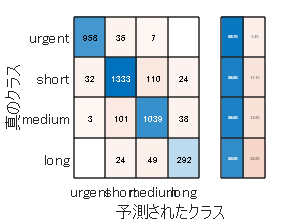

confusionchart(testdata.TTF,ypred,...
    "RowSummary","row-normalized")

4. 各カテゴリー分布を確認したのですがどうすればよいですか？

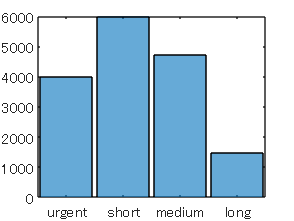

% カテゴリーの分布を確認
histogram(traindata.TTF)

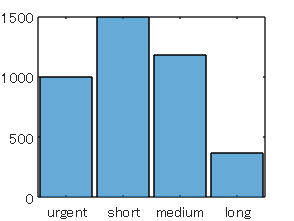

histogram(testdata.TTF)